# Neurostim GUI

Neurostim experiments can run from the command line; many demos show how to do this. Most likely you'll use the command line when creating/designing and debugging experiments. The GUI is most useful in production mode, especially when the person running the experiment is not the same as the person writing the code. 

For instance, most experiments have a few variants ('modes') ; you may have one debug version that uses a simulated observer, another that runs with an eyetracker, and a third that includes an external device for transcranial stimulation or recording EEG. Switching between these modes may require multiple changes in the experiment file, which can lead to errors. 

The person who programmed the experiment should know which changes are necessary to switch between modes, but the person running the experiment (the technician) may not be as familiar with the code or even with Matlab in general. The GUI provides a solution. To prevent errors in the experiment at run time, the programmer exposes only some of the parameters in the experiment in the GUI and the technician can change only those. The GUI also remembers settings per user, per experiment, and per mode; this simplifies running experiments repeatedly.

Another advantage of the GUI is that you can achieve better git-based version tracking. A recommended setup is to have one git repository with your experiments and a separate repository that contains the Neurostim toolbox. In the GUI you can specify which branches of these repositories you wish to use, and the GUI will automatically update each of these repositories to their latest version. This way, a developer can be sure that the person running the experiment always uses the latest version. Moreover, because the experiment files remain unchanged at run time, their exact content (i.e. the git hash ID associated with the current version) can be logged with the experiment. That way the complete code used to run the experiment can be restored at a later time; thus improving reproducibility.

## Running nsGui

You start the Neurostim GUI with the command:

nsGui

The first time, this will startup in the current folder and scan for experiment files in the current folder and all its subfolders. By default an experiment file is an m-file with a name that starts with `run`. If you start the nsGui in the neurostim installation folder, it will find the gui demo files (e.g. `runGuiSimple.m`). 

Your screen will look something like this:

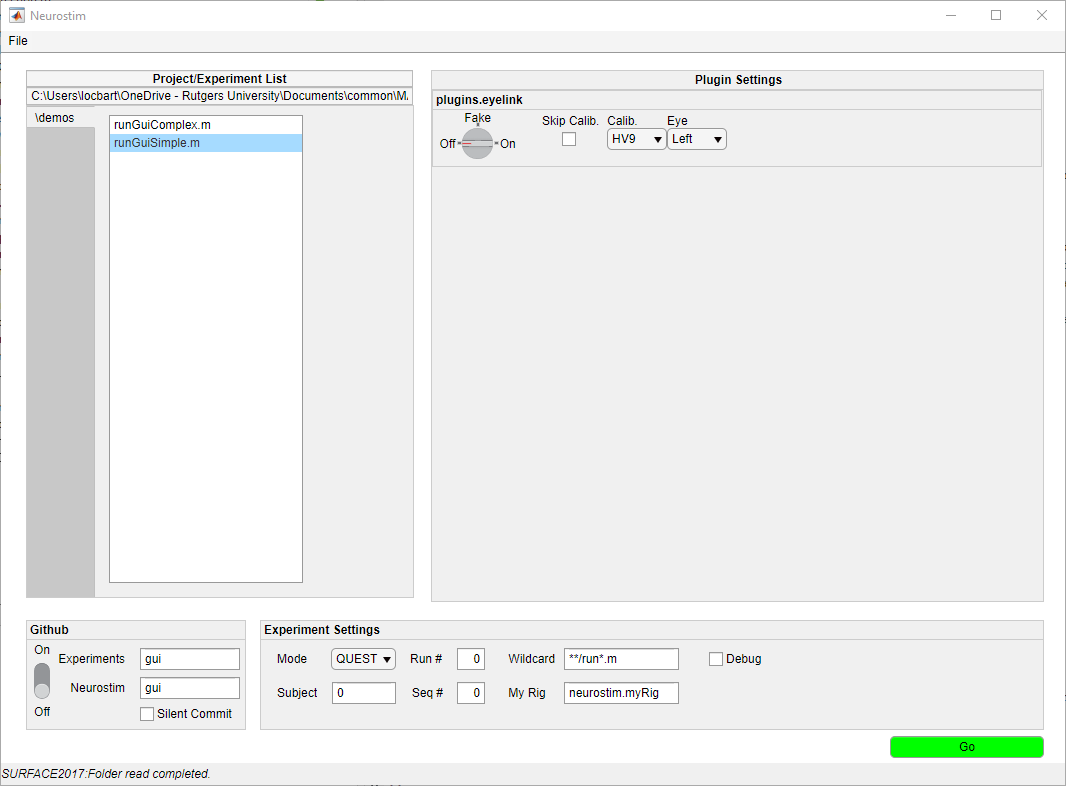

### File Menu

The File menu (Alt F) gives access to 

- Change Root Folder (Alt F+O) : opens a folder dialog box to browse to a folder that contains your experiments. 

- Edit Experiment File (Alt F+E): opens the experiment file that is currently selected (i.e. runGuiSimple.m in the example above).

- Valdiate Bits++  (not implemented yet)

- Reset Preferences (Alt F+R): this is a factory reset for all remembered settings in the GUI.

- Help (Alt F+H): opens the Neurostim documentation.

### Project/Experiment List

The GUI uses the convention that each folder below the root folder is a project, and files inside those folders that match the Wildcard (see Experiment Settings) are considered candidate experiments to run.

The Project/Experiment list shows each project as a tab (the example figure has only one folder with experiment files : "\demos") , and lists the experiments in the seleted project. 

The root folder is listed above the list of experiments; you change it with File |Change Root Folder menu.

When you select one of the experiments in the list, the Plugin Settings panel updates to show panels that are relevant for that experiment. 

### Plugin Settings

This panel shows GUI panels relevant for the currently selected experiment (see Creating gui-enabled experiments how the developer specifies this).

In the figure above, the `runGuiSimple.m` experiment is selected; it has only a single panel with settngs for the eyelink eyetracker (`plugins.eyelink`). This user interface allows the user to turn the eyelink plugin off, on, or to simulate an eye tracker ('fake'). The  color of the panel will change to indicate which of these modes is currently in use. 

The other user interface elements are specific to the eyelink tracker. For instance, there is a choice to skip the calibration at the start of the experiment (Skip Calib), to choose a calibration layout (Calib), and specify which eye to track (Eye). The elements shown here depend on what the developer of the plugin implemented. If the developer implemented no specific user interface, then only the knob to turn the plugin on or off (or fake) will appear. 

If an experiment is not gui-enabled (or something else went wrong when querying the experiment), a red warning appears in the Plugin Settings panel.

### Git

This panel determines interaction with Git. It requires a functioning git installation on your computer and a toolbox that provides git access from inside Matlab: [github.com/manur/MATLAB-git](http://github.com/manur/MATLAB-git). 

The Experiments  box lists the branch of the git repository that contains the experiment files (i.e. the git repository that is cloned into the root folder).  The Neurostim box lists the branch of the Neurostim repository that is currently in use.

At startup, nsGui ensures that these branches are up to date with their remote origin. Specifically, nsGui stashes any local changes, then pulls the latetst version from the remote, merges it and then asks to reapply the local changes (if any). 

If the branch currently checked out differs from the branch specified in the GUI, nsGUI will ask which branch you want to use.

You can switch to a new branch simply by entering its name. As with all paramters, nsGui will remember this for the next run.

When you start an experiment, nsGui checks again whether there are local modifications. Ideally, there are no local mods, in which case nsGui retrieves the hash of the current version of the Experiments and Neurostim repositories and stores these in the Neurostim output file (the `repoVersion `property of `CIC`).

If there are local mods, nsGui will commit these before running the experiment. You will be asked to provide a commit message (or, if you selected Silent Commit) it will generate its own message. Once everything is committed, nsGui retrieves the git hashes after the local commits and stores these. Note that nsGui does not push these commits to the remote; this allows an expert user to check the commit first and modify if needed (of course if the expert reverts the commit, the hash stored in the datafile will become invalid). In typical usage there should never be local changes in the Neurostim toolbox repository, and changes in the experiments repository should be minimal.  

### Experiment Settings

The Mode dropdown box lists the modes for the currently selected experiment; pick one to run. (All plugin settings are remembered per mode, so changing the mode may change the plugin settings.)

Wildcard defines what the GUI considers to be a valid experiment file name. The default` '**/run*.m'` means any m-file whose name starts with `run` in any of the subfolders of the root folder.` '**/*.m`' would show all m-files,etc. This uses Matlab's `dir` function to scan folders recursively, so you can use it to test your wildcards.

My Rig specifies a function (that you define) which sets up default parameters settings based on your laboratory's specific equipment (e.g. monitor pixels, refresh rates, paths for data file saving). The neurostim.myRig function shows an example, but it is recommended that you create your own based on the myRig template and store it in your Experiments repository. 

Checking Debug does not do anything on its own, except passing` 'debug',true` to the My Rig function; in there you can handle this common setting as you wish. 

The Subject, Run, and Seq set those members of CIC and stores them in the output file. 

## Creating gui-enabled experiments

A regular Neurostim experiment file can be changed into a gui-enabled file with just a few lines of code. First, the experiment file has to be a function, with the following prototype:

function c = runMyExperiment(varargin)

end

Starting the name with `run `is optional, but it allows you to separate experiment files from other m-files in the gui (using the Wlidcard).

nsGui will query your experiment file to obtain a list of modes (used to populate the Mode dropdown) and a list of panels (used to fill the Plugin Settings panel). To do this add the following lines of code at the top of your experiment file:

function c = runMyExperiment(varargin)

import neurostim.*

[run,c,settings] = nsGui.parse(varargin{:},...  % Any parameters that the GUI sends (required)
    'Panels',{'plugins.eyelink'},...  % Request the eyelink gui panel
    'Modes',{'QUEST','STAIRCASE'});  % List modes of the experiment
if ~run
    % This was a call only to collect information; return without running the experiment.
    return;
end

%[....]  Your regular experiment code goes here
end
    

The critical part here is the call to `nsGui.parse. `First you need to pass all input arguments (`varargin{:}`), then you specify plugins (or stimuli) that you wish to add to the GUI ('`Panels`'), and finally you specify a list of modes ('`Modes`'). That is all. 

Whenever the selected experiment in the GUI is changed, `nsGui` calls the experiment file to retrieve the list of panels and modes, and uses this to setup the GUI.

When the user presses Go a `cic` object with all requested plugins and settings is created and the experiment file is called again, now resulting in `run=true`, hence execution of your code will start with `c` containing the `CIC` object, and `settings` a `struct` with the selected mode. Your code then uses something like this to do experiment-specific adjustments:

switch upper(settings.mode)
    case 'QUEST'
        %[ ...] Use Quest 
    case 'STAIRCASE'
        %[... ] Use a 1up1down staircase
end

In a little more detail, here are the steps that nsGui performs beind the scenes when you press Go

- create a default `cic` object, 

- add the plugins where the knob is turned to on or fake

- apply all settings in the GUI to the plugins. 

- apply experiment settings to `cic` (e.g. run, seq) 

- create a `settings` struct that contains the value selected for Mode as well as all settings of experiment-defined gui panels (see below). 

- pass the `cic` object and the `settings struct `to the My Rig function for further lab or rig specific settings/modifications

- call the experiment function such that nsGui.parse returns `run=true`, the `c `variable contains the `cic `object, and `settings`, the struct with experiment-defined settings.

## Rolling your own GUI panels

#### Gui Panels for Stimuli and Plugins

Each plugin (which includes stimuli) has a rudimentary gui panel containing only the on/off/fake knob. To add elements to this base panel, the plugin derived class defines a static function called guiLayout. Here, for instance, is example code from `neurostim.plugins.eyelink` :

methods (Static, Access=public)
        
        function guiLayout(p)
            % p is the parent uipanel that contains the onOffFakeKnob
            % add plugin specific elements            
            h = uilabel(p);
            h.HorizontalAlignment = 'left';
            h.VerticalAlignment = 'bottom';
            h.Position = [110 39 60 22];
            h.Text = 'Skip Calib.';
            
            h = uicheckbox(p,'Tag','SkipCal');
            h.Position = [130 17 22 22];
            h.Text = '';
            h.Value=  false;
            h.Tooltip = 'Check to skip calibration at the start of the experiment';
                        
            h = uilabel(p);
            h.HorizontalAlignment = 'left';
            h.VerticalAlignment = 'bottom';
            h.Position = [235 39 60 22];
            h.Text = 'Eye';
            
            h =uidropdown(p,'Tag','Eye');
            h.Position = [235 17 60 22];
            h.Items = {'Left','Right','Both'};
            h.Tooltip = 'Select which eye to track';
            
        end
end      

Note that positioning (relative to the parent uipanel p) uses pixels [left right width height], which may take some trial-and-error to look right. Also, as the app is created with `appdesigner`, odler `GUIDE`-style elements are note allowed. 

Plugins should also define a `guiSet` function, which applies settings to the plugin once it is created. Again, borrowing from the eyelink plugin:

methods (Access= public)
        function guiSet(o,parms)
            % The nsGui calls this just before the experiment starts;
            % o = eyelink plugin
            % parms = struct with settings for each of the elements in the
            % guiLayout, named after the Tag property
            %
            o.doTrackerSetup    = ~parms.SkipCal;
            o.eye               = parms.Eye;
            o.fake              = strcmpi(parms.onOffFakeKnob,'fake');
            
        end
    end

Note how the `guiSet` function uses the Tag names set in the `guiLayout` function.

#### Gui Panels for a Specific Experiment

Sometimes an experiment has settings that cannot be captured easily in a single Mode selection.In this case, you may want to define a gui panel specifc for that experiment. To do this you define a function that takes a single input argument (the handle to the enclosing empty uipanel), in that function you add user interface elements just as you would for a plugin (above), making sure to use a Tag for each element that corresponds to a setting you wish to expose to the user. An example of this is shown in `runGuiComplex.m. `

 function myPanel(p)
        % Add a checkbox that will toggle a simulated observer
        h = uilabel(p); % Add a label to the panel parent
        h.HorizontalAlignment = 'left';
        h.VerticalAlignment = 'bottom';
        h.Position = [5 39 60 22];
        h.Text = 'Pianola';
        h = uicheckbox(p,'Tag','pianola'); % Add a checkbox to the panel parent.
        % The 'pianola' Tag ensures that at run time settings.pianola will have the value set in the gui
        % Note that this is case-sensitive
        h.Position = [5 17 22 22];
        h.Text = '';
        h.Value=  false;
        h.Tooltip = 'Check to run a simulated observer.';
               
    end

The only other requirement for this function is that Matlab can execute it at run time, so it can be nested in the experiment, or you can define it in an m-file on the Matlab search path. 

To instruct nsGui to use this panel in the GUI, just add a handle to the function to the 'Panels' list

[run,c,settings] = nsGui.parse(varargin{:},...  
    'Panels',{'plugins.eyelink',@myPanel},...
   

At run time, in the experiment file, the `settings` struct will have the values set in the GUI. For instance, in this example `settings.pianola `will have the value of the checkbox in `myPanel`. 

## Limitations

Settings in the GUI are applied before the start of the experiment, but any mid-experiment changes to the GUI are not immediately passed to the running experiment. In other words, this is not a live/online GUI. This means that the GUI is not (yet) suitable for changes that can be made on the fly (e.g. reward size, eye position tolerance).

Once you've added the code to gui-enable the experiment, running it without the GUI is not straightforward. One thing a developer could do is to add their own manual setup code in the experiment file to parse the varargin passed to the experiment function (To simplify this, `nsGui.parse `will ignore unmatched elements). 

Or, a simple way to start an experiment is to call the experiment file with a pre-filled `cic` and mode. 

c= myRig() ;% Create a cic using your myRig function
%[...]% Set cic settings at will
% Then pPass c to the experiment with 'do', 'run' and specify a mode
runExperiment('do','run','cic',c,'mode','staircase'); 